# Example for FASTCORMICS

addpath(genpath(pwd))
feature astheightlimit 2000 %needed for some large models to be able to use eval()

ans = 'feature astHeightLimit 2000'

load data from Barcode

previosuly generated from GSE49910

barcode = readtable('barcode.txt', 'ReadRowNames',false); %change ReadRowNames to true if rownames are present
rownames = textread('rownames.txt','%s'); %read row file from barcode
colnames = textread('colnames.txt','%s'); %read probeIDs from barcode

set colnames and conditions (if needed)

B_cell = [1:4];
Neutrophil = [5:7];

conditions = {B_cell, Neutrophil};
condition_names = {'B_cell', 'Neutrophil'};

# Model creation

## Discretize data

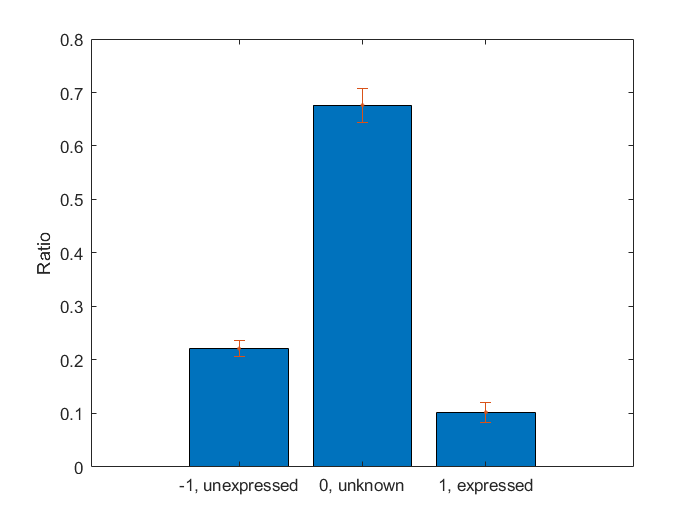

discretized = table2array(barcode);

%set thresholds
expression_threshold      = 5; %5 frma you might want to lower this threshold to 3 if the models are too small.
inexpression_threshold    = 0; %0 frma

match_expressed     = table2array(barcode) > expression_threshold;
match_unexpressed   = table2array(barcode) <= inexpression_threshold;
match_unknown       = table2array(barcode) <= expression_threshold & table2array(barcode) > inexpression_threshold;
%apply thresholds
discretized(match_expressed)   = 1;
discretized(match_unexpressed) = -1;
discretized(match_unknown)     = 0;

figure
bar([mean(sum(discretized==-1));mean(sum(discretized==0));mean(sum(discretized==1))]/size(discretized,1))
hold on
errorbar([mean(sum(discretized==-1));mean(sum(discretized==0));mean(sum(discretized==1))]/size(discretized,1),...
    [std(sum(discretized==-1));std(sum(discretized==0));std(sum(discretized==1))]/size(discretized,1),'.')
set(gca, 'XTickLabel', {'-1, unexpressed','0, unknown','1, expressed'})
ylabel('Ratio')


clear data expression_threshold inexpression_threshold match_expressed match_unexpressed match_unknown

## Setup

load('Data\Recon204.mat','CmodelR204')
Cmodel = CmodelR204; clear CmodelR204

load('Data\hgu133plus2dico.mat') %allows to map probeIDs/rownames to model. Can be generated using BioMart and imported into Matlab
dico = hgu133plus2dico;


load('Data\RPMI_charstrippedFBS_DHT_MTA_content') % need to define medium for the cells used here

epsilon = 1e-4;
consensus_proportion = 0.9; %gene has to be expressed in 90% of the cases in order to be included.
% Only relevant if you want to create one model from different samples
already_mapped_tag = 0;

unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = Cmodel.rxns(ismember(Cmodel.subSystems,unpenalizedSystems));


optional_settings.unpenalized = unpenalized;
optional_settings.func = {'DM_atp_c_'};

not_medium_constrained = {'EX_tag_hs(e)'};
optional_settings.not_medium_constrained = not_medium_constrained;
optional_settings.medium = RPMI_FBS_content;

biomass_rxn = {'biomass_reaction'};

biomass_rxn = 1×1 cell array
    {'biomass_reaction'}


## Create models

#### Create single models

for i=1:numel(colnames(:,1))
    [~, A_final{i}] = fastcormics(Cmodel, discretized(:,i), rownames, dico, biomass_rxn, already_mapped_tag,...
        consensus_proportion, epsilon, optional_settings);
end

2060 of 2140 genes matched


delete *.log

% create models_keep_generic
models_keep_single = zeros(numel(Cmodel.rxns), numel(colnames(:,1)));
for i=1:numel(colnames(:,1))
    models_keep_single(A_final{i},i) = 1;
end


J = squareform(pdist(models_keep_single','jaccard'));
cgo = clustergram(1-J,...
    'RowLabels', colnames(:,1),...
    'ColumnLabels', colnames(:,1),...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)
addTitle(cgo, {'Clustergram for single models', 'Jaccard index on reaction presence in models', 'with medium'},'Interpreter','none')

#### Create generic models

for i=1:numel(condition_names)
    [~, A_final{i}] = fastcormics(Cmodel, discretized(:,conditions{i}), rownames, dico, already_mapped_tag,...
        consensus_proportion, epsilon, optional_settings);
end

delete *.log
%     create models_keep_generic
models_keep_generic = zeros(numel(Cmodel.rxns), numel(condition_names));
for i=1:numel(condition_names)
    models_keep_generic(A_final{i},i) = 1;
end

J = squareform(pdist(models_keep_generic','jaccard'));
cgo = clustergram(1-J,...
    'RowLabels', condition_names,...
    'ColumnLabels', condition_names,...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)
addTitle(cgo, {'Clustergram for generic models', 'Jaccard index on reaction presence in models', 'with medium'},'Interpreter','none')